syms u p1 p2 p3
x= (1-u)*((1-u)*p1+u*p2)+ u*((1-u)*p2+u*p3)

$$x = u\,\left(p_{3}\,u-p_{2}\,\left(u-1\right)\right)-\left(p_{2}\,u-p_{1}\,\left(u-1\right)\right)\,\left(u-1\right)$$

f= 1-(-(1-u)+ 2)* (1-u)^3

$$f = {\left(u-1\right)}^{3}\,\left(u+1\right)+1$$


P1=[0;0];
P2=[7;3];
P3=[3;1];
P4=[1;4];

P12 = (P1+P2)/2;
P23 = (P2+P3)/2;
P34 = (P3+P4)/2;

u=0:0.1:1;

fu= 2*(-2/4*u.^4+ 3/3* u.^3);
fu= (-u+ 2).* u.^3;
fuv= (-2*u.^3+ 3* u.^2);

x= (1-fu)*P1(1)+fu*P12(1)

x =          0    0.0067    0.0504    0.1607    0.3584    0.6563    1.0584    1.5606    2.1504    2.8067    3.5000


y= (1-fu)*P1(2)+fu*P12(2)

y =          0    0.0029    0.0216    0.0689    0.1536    0.2813    0.4536    0.6688    0.9216    1.2029    1.5000


X = x;
Y = y;
%plot(0.5+u/2,[x;y])
plot(u,[x;y])
grid on
hold on
x= (1-u).^2.*P12(1)+2*(1-u).*u*P2(1)+ u.*u*P23(1)

x =     3.5000    4.1450    4.6800    5.1050    5.4200    5.6250    5.7200    5.7050    5.5800    5.3450    5.0000


y= (1-u).^2.*P12(2)+2*(1-u).*u*P2(2)+ u.*u*P23(2)

y =     1.5000    1.7750    2.0000    2.1750    2.3000    2.3750    2.4000    2.3750    2.3000    2.1750    2.0000


X = [X,x(2:end)];
Y = [Y,y(2:end)];
plot(1+u,[x;y])

x= (1-u).^2.*P23(1)+2*(1-u).*u*P3(1)+ u.*u*P34(1)

x =     5.0000    4.6100    4.2400    3.8900    3.5600    3.2500    2.9600    2.6900    2.4400    2.2100    2.0000


y= (1-u).^2.*P23(2)+2*(1-u).*u*P3(2)+ u.*u*P34(2)

y =     2.0000    1.8250    1.7000    1.6250    1.6000    1.6250    1.7000    1.8250    2.0000    2.2250    2.5000


X = [X,x(2:end)];
Y = [Y,y(2:end)];
plot(2+u,[x;y])

fud= 1-fliplr(fu)

fud =          0    0.1981    0.3856    0.5541    0.6976    0.8125    0.8976    0.9541    0.9856    0.9981    1.0000


fu= 1-(-(1-u)+ 2).* (1-u).^3;
x= (1-fud)*P34(1)+fud*P4(1)

x =     2.0000    1.8019    1.6144    1.4459    1.3024    1.1875    1.1024    1.0459    1.0144    1.0019    1.0000


y= (1-fud)*P34(2)+fud*P4(2)

y =     2.5000    2.7971    3.0784    3.3312    3.5464    3.7188    3.8464    3.9311    3.9784    3.9971    4.0000


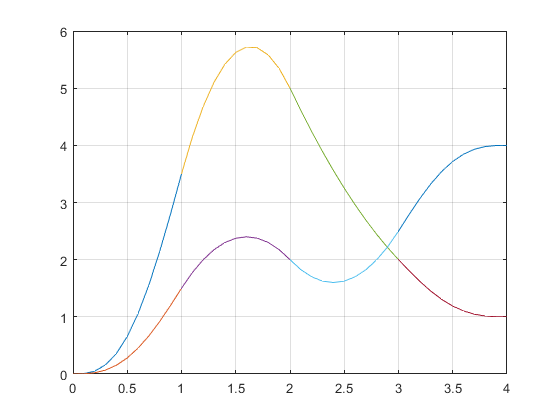

X = [X,x(2:end)];
Y = [Y,y(2:end)];
plot(3+u,[x;y])
hold off

% @f(u) = (-2/4*u.^4+ 3/3* u.^3);

U=[(-2/4*u.^4+ 3/3* u.^3),0.5+u(2:end),1.5+u(2:end),3-(-2/4*(1-u(2:end)).^4+ 3/3* (1-u(2:end)).^3)]

U =          0    0.0010    0.0072    0.0230    0.0512    0.0938    0.1512    0.2229    0.3072    0.4010    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.5991    2.6928    2.7771    2.8488    2.9063    2.9488    2.9771    2.9928    2.9990    3.0000
